% =========================================================================
% Classification Results Visualization Script
% =========================================================================
% This script loads the saved classifier results and creates visualizations
% to compare the performance of models trained on:
%   1. All Features (EMG + Motion)
%   2. EMG Features Only
%
% Visualizations Created:
%   - Bar chart of overall model accuracies.
%   - Confusion matrices for all models and feature sets.
%   - Detailed per-class metrics (Precision, Recall, F1-Score) table.
% =========================================================================

clear;
clc;
close all; % Close all existing figures

## Step 1: Load and Prepare Data

fprintf('=== Step 1: Loading Classifier Results ===\n');

=== Step 1: Loading Classifier Results ===



% Define the path to the results file
resultsFile = './ClassificationResult/ClassifierResults_Comparison.mat';

% Check if the results file exists
if ~exist(resultsFile, 'file')
    error('Results file not found: %s\nPlease run the classification script first.', resultsFile);
end

% Load the data
load(resultsFile);

% Extract key variables for easier access
true_labels = results.true_labels;
class_names = results.class_names;
num_classes = length(class_names);

% Extract accuracies and predictions, handling cases where a model might have failed
% All Features
acc_all = [
    results.all_features.rf_accuracy, ...
    results.all_features.svm_accuracy, ...
    results.all_features.xgb_accuracy
] * 100; % Convert to percentage

pred_all.rf  = results.all_features.rf_predictions;
pred_all.svm = results.all_features.svm_predictions;
pred_all.xgb = results.all_features.xgb_predictions;

% EMG Only Features
acc_emg = [
    results.emg_only.rf_accuracy, ...
    results.emg_only.svm_accuracy, ...
    results.emg_only.xgb_accuracy
] * 100; % Convert to percentage

pred_emg.rf  = results.emg_only.rf_predictions;
pred_emg.svm = results.emg_only.svm_predictions;
pred_emg.xgb = results.emg_only.xgb_predictions;

fprintf('✓ Results loaded successfully.\n');

✓ Results loaded successfully.


## Step 2: Visualize Overall Accuracy Comparison

fprintf('\n=== Step 2: Generating Overall Accuracy Plot ===\n');


=== Step 2: Generating Overall Accuracy Plot ===


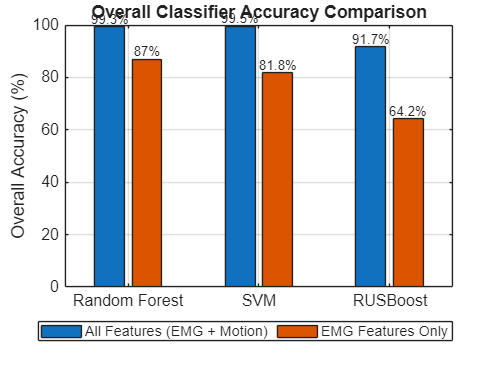


figure('Name', 'Overall Model Accuracy Comparison', 'Position', [100, 200, 800, 600]);
model_names = {'Random Forest', 'SVM', 'RUSBoost'};
bar_data = [acc_all', acc_emg']; % Group accuracies for plotting

b = bar(bar_data, 'grouped');
ylabel('Overall Accuracy (%)');
title('Overall Classifier Accuracy Comparison');
set(gca, 'XTickLabel', model_names, 'FontSize', 12);
ylim([0, 100]);
grid on;

% Add legend
legend({'All Features (EMG + Motion)', 'EMG Features Only'}, 'Location', 'southoutside', 'Orientation', 'horizontal');

% Add text labels on top of bars
for i = 1:length(b)
    xtips = b(i).XEndPoints;
    ytips = b(i).YEndPoints;
    labels = string(round(b(i).YData, 1)) + '%';
    text(xtips, ytips, labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom');
end


fprintf('✓ Accuracy comparison plot created.\n');

✓ Accuracy comparison plot created.


## Step 3: Visualize Confusion Matrices

fprintf('\n=== Step 3: Generating Confusion Matrices ===\n');


=== Step 3: Generating Confusion Matrices ===


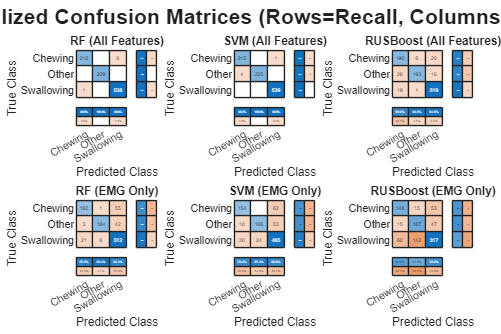


figure('Name', 'Confusion Matrices', 'Position', [200, 100, 1200, 800]);
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact'); % Create a 2x3 grid

% --- Row 1: All Features ---
% Random Forest (All)
nexttile;
cm_rf_all = confusionmat(true_labels, pred_all.rf);
confusionchart(cm_rf_all, class_names, ...
    'Title', 'RF (All Features)', ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

% SVM (All)
nexttile;
cm_svm_all = confusionmat(true_labels, pred_all.svm);
confusionchart(cm_svm_all, class_names, ...
    'Title', 'SVM (All Features)', ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

% RUSBoost (All)
nexttile;
cm_xgb_all = confusionmat(true_labels, pred_all.xgb);
confusionchart(cm_xgb_all, class_names, ...
    'Title', 'RUSBoost (All Features)', ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

% --- Row 2: EMG Only ---
% Random Forest (EMG)
nexttile;
cm_rf_emg = confusionmat(true_labels, pred_emg.rf);
confusionchart(cm_rf_emg, class_names, ...
    'Title', 'RF (EMG Only)', ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

% SVM (EMG)
nexttile;
cm_svm_emg = confusionmat(true_labels, pred_emg.svm);
confusionchart(cm_svm_emg, class_names, ...
    'Title', 'SVM (EMG Only)', ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

% RUSBoost (EMG)
nexttile;
cm_xgb_emg = confusionmat(true_labels, pred_emg.xgb);
confusionchart(cm_xgb_emg, class_names, ...
    'Title', 'RUSBoost (EMG Only)', ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

sgtitle('Normalized Confusion Matrices (Rows=Recall, Columns=Precision)', 'FontSize', 16, 'FontWeight', 'bold');


fprintf('✓ Confusion matrix plot created.\n');

✓ Confusion matrix plot created.


## Step 4: Display Detailed Per-Class Metrics

fprintf('\n=== Step 4: Calculating Detailed Per-Class Metrics ===\n');


=== Step 4: Calculating Detailed Per-Class Metrics ===



% Note: We already calculated the confusion matrices in Step 3
% so we can reuse them here

% Display the tables
display_metrics('All Features - Random Forest', cm_rf_all, class_names);


--- All Features - Random Forest ---
Class           | Precision  | Recall     | F1-Score  
-------------------------------------------------------
Chewing         |   0.995    |   0.972    |   0.984
Swallowing      |   0.989    |   0.998    |   0.994
Other           |   1.000    |   1.000    |   1.000


display_metrics('All Features - SVM', cm_svm_all, class_names);


--- All Features - SVM ---
Class           | Precision  | Recall     | F1-Score  
-------------------------------------------------------
Chewing         |   0.982    |   0.995    |   0.989
Swallowing      |   0.998    |   1.000    |   0.999
Other           |   1.000    |   0.983    |   0.991


display_metrics('All Features - RUSBoost', cm_xgb_all, class_names);


--- All Features - RUSBoost ---
Class           | Precision  | Recall     | F1-Score  
-------------------------------------------------------
Chewing         |   0.809    |   0.880    |   0.843
Swallowing      |   0.945    |   0.963    |   0.954
Other           |   0.965    |   0.843    |   0.900



display_metrics('EMG Only - Random Forest', cm_rf_emg, class_names);


--- EMG Only - Random Forest ---
Class           | Precision  | Recall     | F1-Score  
-------------------------------------------------------
Chewing         |   0.870    |   0.741    |   0.800
Swallowing      |   0.841    |   0.950    |   0.892
Other           |   0.963    |   0.803    |   0.876


display_metrics('EMG Only - SVM', cm_svm_emg, class_names);


--- EMG Only - SVM ---
Class           | Precision  | Recall     | F1-Score  
-------------------------------------------------------
Chewing         |   0.794    |   0.713    |   0.751
Swallowing      |   0.808    |   0.900    |   0.852
Other           |   0.874    |   0.725    |   0.792


display_metrics('EMG Only - RUSBoost', cm_xgb_emg, class_names);


--- EMG Only - RUSBoost ---
Class           | Precision  | Recall     | F1-Score  
-------------------------------------------------------
Chewing         |   0.609    |   0.685    |   0.645
Swallowing      |   0.760    |   0.588    |   0.663
Other           |   0.515    |   0.729    |   0.604



fprintf('\n✓ All visualizations and metric reports are complete.\n');


✓ All visualizations and metric reports are complete.


## Helper function to calculate and display metrics from a confusion matrix

function display_metrics(title_str, C, class_names)
    fprintf('\n--- %s ---\n', title_str);
    fprintf('%-15s | %-10s | %-10s | %-10s\n', 'Class', 'Precision', 'Recall', 'F1-Score');
    fprintf('%s\n', repmat('-', 1, 55));
    
    diag_C = diag(C);
    sum_rows = sum(C, 2); % Actual positives (for Recall)
    sum_cols = sum(C, 1)'; % Predicted positives (for Precision)
    
    % Calculate metrics for each class
    precision = diag_C ./ sum_cols;
    recall = diag_C ./ sum_rows;
    f1_score = 2 * (precision .* recall) ./ (precision + recall);
    
    % Handle potential NaN cases (division by zero)
    precision(isnan(precision)) = 0;
    recall(isnan(recall)) = 0;
    f1_score(isnan(f1_score)) = 0;
    
    for i = 1:length(class_names)
        fprintf('%-15s |   %.3f    |   %.3f    |   %.3f\n', ...
            class_names{i}, precision(i), recall(i), f1_score(i));
    end
end